### Radioactive Decay

- Non-linear function - take natural log of both sides of equation to make it linear

- New fit parameters

- Do error propagation

- Add column R = N/t, uncertainty on R

- Find uncertainty on lnR, uncertainty on other fit variables

data = dlmread('PHYS 3605W/Workshops/PHYS_3605_wkshop_3_data.csv',',', [1,0,11,6]);

###   
$$R=R_o e^{-\frac{l}{\lambda }}$$
                

N_plates = data(:,1);
N_beta = data(:,2); 
N_beta_err = data(:,3);
t = data(:,4); %seconds
t_err = data(:,5); %seconds
R = data(:,6); % number of beta / second
R_err = sqrt(N_beta_err.^2.*(1./t).^2 + t_err.^2.*(-N_beta./t.^2).^2);
l = N_plates.*0.002; % meters
sz = size(l);
l_err = 0.00004.*ones(sz); % meters


To obtain linear fit, I'll convert to 

###  
$$\mathrm{ln}\left(R\right)=\mathrm{ln}\left(R_o \right)-\frac{1}{\lambda }l$$
                     
$$\sigma_{\mathrm{lnR}}^2 =\sigma_N^2 {\left(\frac{1}{N}\right)}^2 +\sigma_t^2 {\left(-\frac{1}{t}\right)}^2$$


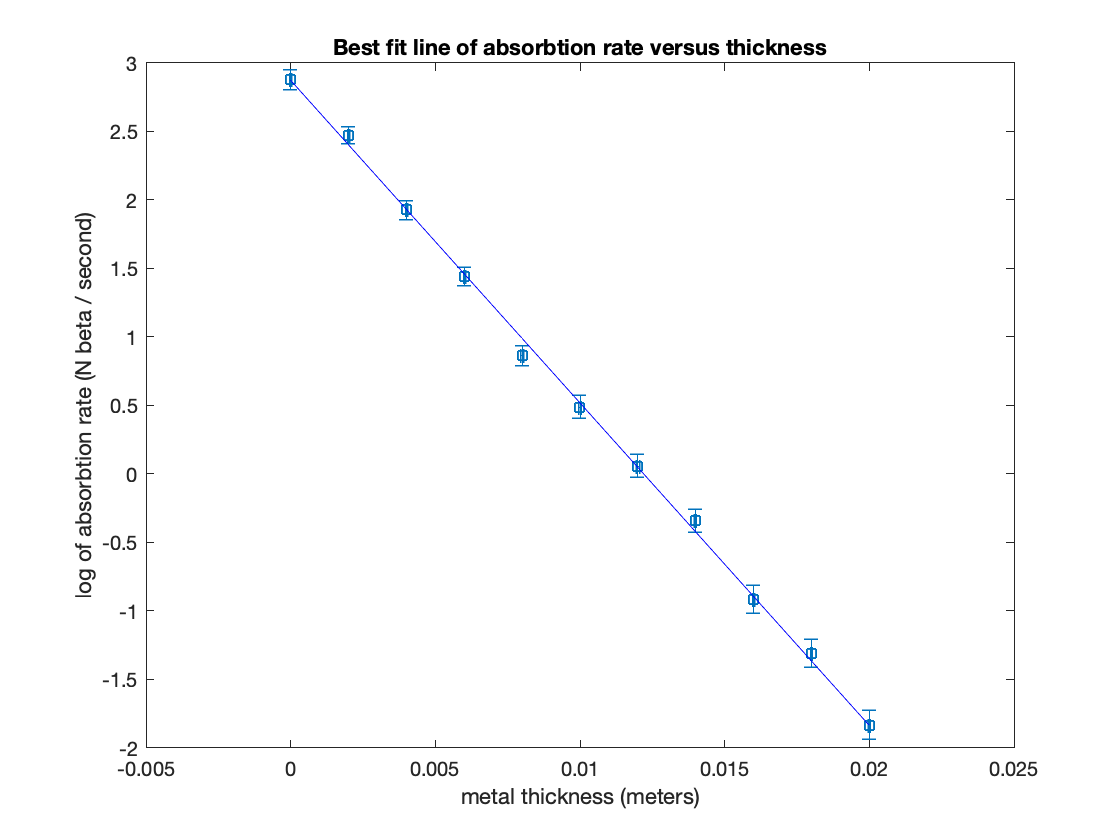

y = log(R);
y_err = sqrt(N_beta_err.^2.*(1./N_beta).^2 + t_err.^2.*(-1./t).^2);
x = l;
fit_vals = myfit(x,y,y_err);
a = fit_vals(1,1);
b = fit_vals(1,2);
ea = fit_vals(2,1);
eb = fit_vals(2,2);

fit_y = a + x.*b;

xneg = l_err;
xpos = l_err;
yneg = y_err;
ypos = y_err;
errorbar(x,y,yneg,ypos,xneg,xpos,'s','DisplayName', 'fit data')
title('Best fit line of absorbtion rate versus thickness')
xlabel('metal thickness (meters)')
ylabel('log of absorbtion rate (N beta / second)')

hold on
plot(x, fit_y, 'b', 'DisplayName', 'y Fit')
hold off

###   
$$\sigma_{\lambda }^2 =\sigma_b^2 {\left(\frac{1}{b^2 }\right)}^2$$


lamda = -1/b

lamda = 0.0042

lamda_err = sqrt(eb^2*(1/b^2)^2)

lamda_err = 7.3037e-05

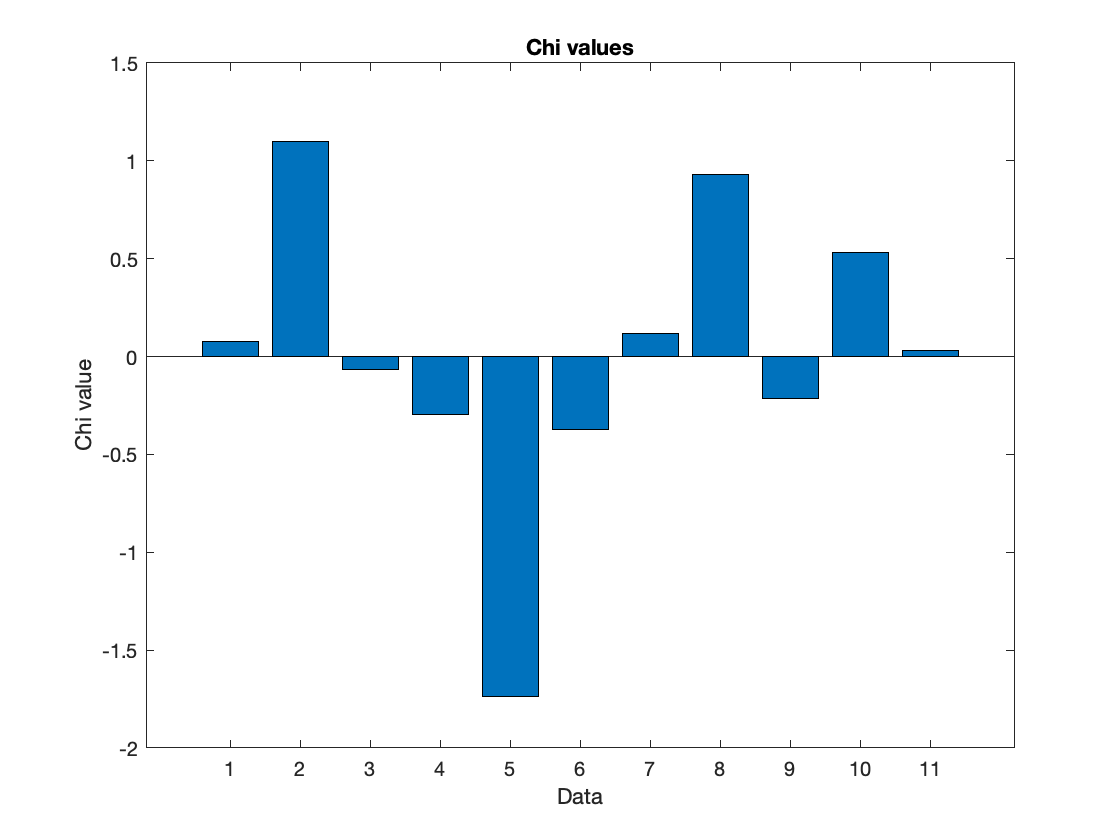


chi_data = getChi(y, fit_y, y_err);
chi = chi_data(:,1);
chi_squared = chi_data(:,2);

bar(chi)
title('Chi values')
xlabel('Data')
ylabel('Chi value')

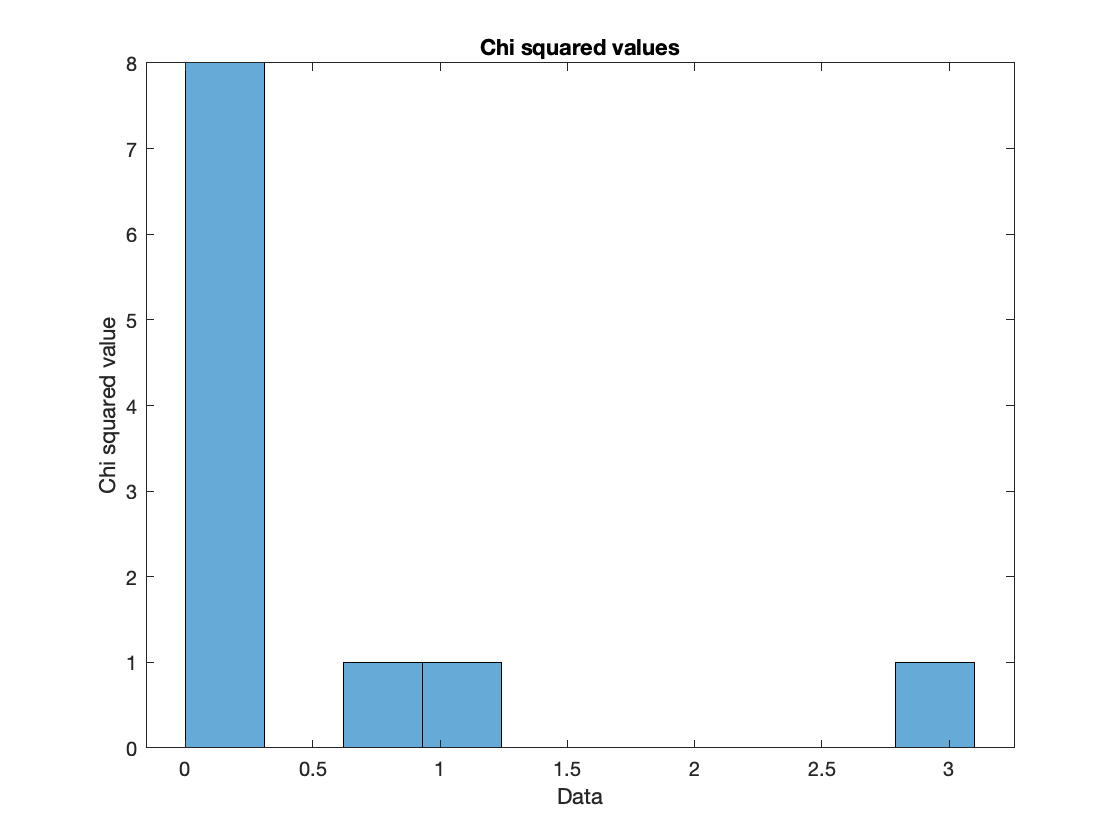


histogram(chi_squared, 10)
title('Chi squared values')
xlabel('Data')
ylabel('Chi squared value')

Using the linear fit, I obtained a $\lambda =0\ldotp 0042\pm \;\;0\ldotp 0007\;m$

function rval = myfit(x,y,ey)
  sx = sum(x ./ (ey .^ 2) );
  sy = sum(y ./ (ey .^ 2) );
  sxx = sum((x .* x) ./ (ey .^ 2) );
  sxy = sum((x .* y) ./ (ey .^ 2) );
  s = sum(1 ./ (ey .^ 2) );
  delta=sxx*s-sx*sx;
  a=(sxx*sy-sx*sxy)/delta;
  ea=sqrt(sxx/delta);
  b=(s*sxy-sx*sy)/delta;
  eb=sqrt(s/delta);
  rval=[ a, b ; ea, eb];
end

function chi_vals = getChi(y, fit_y, y_err)
   chi = (y - fit_y)./(y_err);
   chi2 = chi.^2;
   chi_vals = [chi, chi2];
end